# Obserevers Design

JJRATH- Feb2021 Closed Loop Luenberger Observer Design

%--------------------------
%----------------------------
% Ex: Active Suspension System
qcar_CT = SISO_Nom_Suspension; % The nominal suspension model
t = 0:.01:10-0.01;
% CASE A: Nominal Model without the disturbance
%- Desired Poles
%---- Controller
Pc_des = [-.1+5.2457i,-.1-5.2457i,-1+42.6209i,-1-42.6209i ]; % Contorller Poles Desired
K_c = place(qcar_CT.a,qcar_CT.b(:,1),Pc_des); % Determines the gain K for the A, B and desired poles
%--- Observer
Po_des = Pc_des*15;
L=place(qcar_CT.a',qcar_CT.c',Po_des); L = L';

## Closed loop observer-contorller dynamics

Ar = [(qcar_CT.a-qcar_CT.b*K_c) qcar_CT.b*K_c; 
    zeros(size(qcar_CT.a)) (qcar_CT.a-L*qcar_CT.c)]; % Using Separation Principle 
Br = [qcar_CT.b;zeros(size(qcar_CT.b))]; 
Cr = [qcar_CT.c zeros(size(qcar_CT.c))]; 
Dr = qcar_CT.d; 
%--- SS Model 
CLKo_qcarCT = ss(Ar,Br,Cr,Dr); 
% The states are those of controlled system and the errors in estimation %% Simulate Response 
% %-- Open Loop Uncontrolled System 
% %--- System response of SS considering u2 = road disturbance, but 
u1 = 0 

u1 =      0


u_f = 0*ones(1,length(t)); 
% No Input to system 
x0_o = [0.01 0.1 0.5 .1]; 
% Initial conditions are non- zero. %--- Simulate 
[Yo,t,Xo] = lsim(qcar_CT,u_f,t,x0_o); 
% We want ouput, state information %- Closed loop observer based controller system 
x0_e = [0.01 0 0 0]; 
% Initial conditions are zero for the estimation error 
% %--- Simulate 
[Yoc,t,Xoc] = lsim(CLKo_qcarCT,u_f,t,[x0_o';x0_e']); 

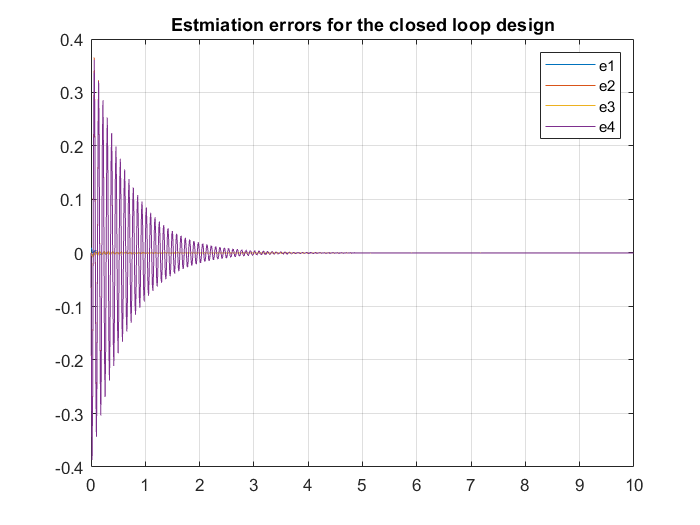

% We want ouput, state information %% Plot Response figure; 
for i= 5:8 
    plot(t,Xoc(:,i)); 
    grid on; 
    hold on; 
end 
legend('e1','e2','e3','e4') 
title('Estmiation errors for the closed loop design') 

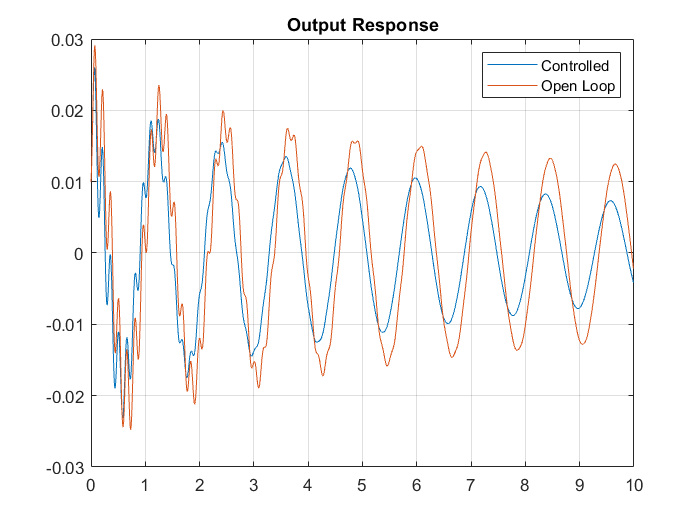

figure; plot(t,Yoc(:,1)); hold on; grid on; plot(t,Yo(:,1)); legend('Controlled','Open Loop') 
title('Output Response')


% CASE B: The disturbed suspension system

qcar_CT = SISO_Dis_suspension; % The disturbed suspension model
t = 0:.01:10-0.01;
%---- Controller
Pc_des = [-.1+5.2457i,-.1-5.2457i,-1+42.6209i,-1-42.6209i ]; % Contorller Poles Desired
K_c = place(qcar_CT.a,qcar_CT.b(:,1),Pc_des); % Determines the gain K for the A, B and desired poles
%--- Observer
Po_des = Pc_des*15;
L=place(qcar_CT.a',qcar_CT.c',Po_des); L = L';

## Closed loop observer-contorller dynamics

Ar = [(qcar_CT.a-qcar_CT.b(:,1)*K_c) qcar_CT.b(:,1)*K_c;
     zeros(size(qcar_CT.a)) (qcar_CT.a-L*qcar_CT.c)]; % Using Separation Principle
Br1 = [qcar_CT.b(:,1);
    zeros(size(qcar_CT.b(:,1)))];
Br2 = [qcar_CT.b(:,2); % The disturbance matrix 
    qcar_CT.b(:,2)];
Br = [Br1,Br2];
Cr = [qcar_CT.c zeros(size(qcar_CT.c))];
Dr = [qcar_CT.d];
%--- SS Model
CLKo_qcarCT  = ss(Ar,Br,Cr,Dr); % The states are those of controlled system and the errors in estimation with disturbance terms

## Simulate Response

%-- Open Loop Uncontrolled System
%--- System response of SS considering u2 = road disturbance, but  u1 = 0
u_f = 0*ones(1,length(t)); % No Input to system
u_road = 0.1*ones(1,length(t)); % Step road disturbance
x0_o = [0.01 0.1 0.5 .1]; % Initial conditions are  non- zero.
%--- Simulate 
[Yo,t,Xo] = lsim(qcar_CT,[u_f;u_road],t,x0_o); % We want ouput, state information
%- Closed loop observer based controller system
x0_e = [0.01 0 0 0]; % Initial conditions are  zero for the estimation error
%--- Simulate 
[Yoc,t,Xoc] = lsim(CLKo_qcarCT,[u_f;u_road],t,[x0_o';x0_e']); % We want ouput, state information

## Plot Response

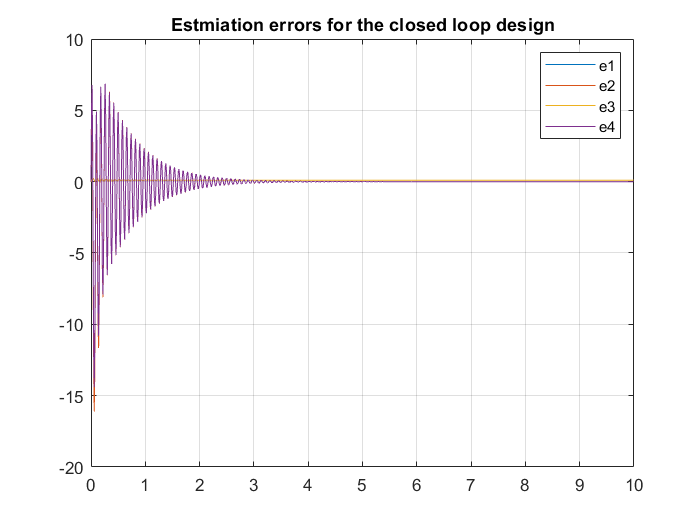

figure; 
for i= 5:8
plot(t,Xoc(:,i)); grid on; hold on;
end
legend('e1','e2','e3','e4')
title('Estmiation errors for the closed loop design')

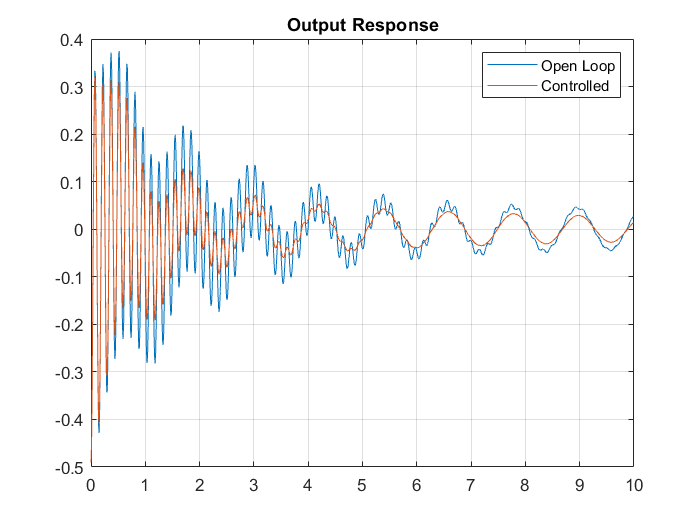

figure;
plot(t,Yo(:,1)); hold on; grid on; plot(t,Yoc(:,1)); 
legend('Open Loop','Controlled')
title('Output Response')